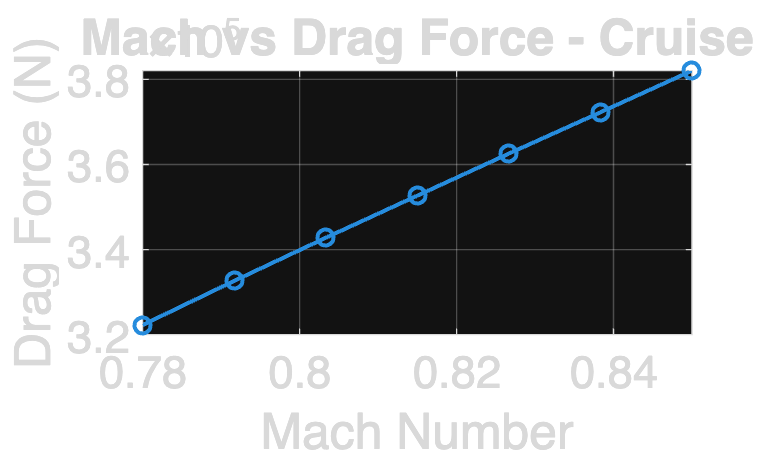

%% Mach vs Drag Force - Cruise
clear
clc

baseDir = fileparts(matlab.desktop.editor.getActiveFilename);
filePath = fullfile(baseDir, '../+lookup/+aerodynamics/cruise_lookup_table.mat');
S = load(filePath);
R = S.Results;

% Fixed geometry / flight condition
span = 73.5;
rootChord = 15.2;
altitude = 9500;
alpha = 2.2;

span = S.spanVec(nearestIndex(S.spanVec, span));
rootChord = S.rootChordVec(nearestIndex(S.rootChordVec, rootChord));
altitude = S.altVec(nearestIndex(S.altVec, altitude));

% Get all available Mach numbers for this geometry and altitude
machVals = S.machVec;

Drag = zeros(size(machVals));

% You may need to replace this with your actual aircraft reference area
Sref = 740; % m^2

% Atmosphere at fixed altitude
[rho, a] = cast.atmos(altitude);

for n = 1:numel(machVals)
    mach = machVals(n);

    idx = [R.WingSpan] == span & ...
          [R.Mach] == mach & ...
          [R.RootChord] == rootChord & ...
          [R.Altitude] == altitude;

    A  = [R(idx).Alpha];
    CD = [R(idx).CD] + 0.018;

    [A, ord] = sort(A);
    CD = CD(ord);

    CDq = interp1(A, CD, alpha, 'linear', 'extrap');

    V = mach * a;
    q = 0.5 * rho * V^2;

    Drag(n) = q * Sref * CDq;
end

figure
plot(machVals, Drag, '-o', 'LineWidth', 1.5)
grid on
xlabel('Mach Number', 'FontSize', 18)
ylabel('Drag Force (N)', 'FontSize', 18)
title('Mach vs Drag Force - Cruise', 'FontSize', 22)


function k = nearestIndex(vec, x)
    [~, k] = min(abs(vec - x));
end